# Bonus Task

## Task 1 - Computing the FFT

raw_speed = squeeze(rotorSpeedData.Data);
time_vec = rotorSpeedData.Time;
plot(time_vec, raw_speed);

%speed_signal = raw_speed - mean(raw_speed);
%plot(time_vec, speed_signal);
L = length(raw_speed);          % Length of the Signal
Ts = mean(diff(time_vec));       % Sampling period (average)
Fs = 1/Ts;                       % Sampling Frequency (Hz)

Y = fft(raw_speed);             % Computing the Fast Fourier Transform

P2 = abs(Y/L);                  % Computing the two sided spectrum P2

% Compute the single-sided spectrum P1 based on P2 and the even-valued signal length L
P1 = P2(1:floor(L/2)+1);
P1(2:end-1) = 2*P1(2:end-1);

% Define the Frequency Domain f
f = Fs*(0:floor(L/2))/L;

%% 4. Plot the Single-Sided Amplitude Spectrum
figure;
plot(f, P1, 'LineWidth', 1.5);
title('Single-Sided Amplitude Spectrum of Rotor Speed');
xlabel('Frequency (Hz)');
ylabel('|P1(f)| (Magnitude)');
grid on;

## Task 6 (Simulink - Simscape Comparision)

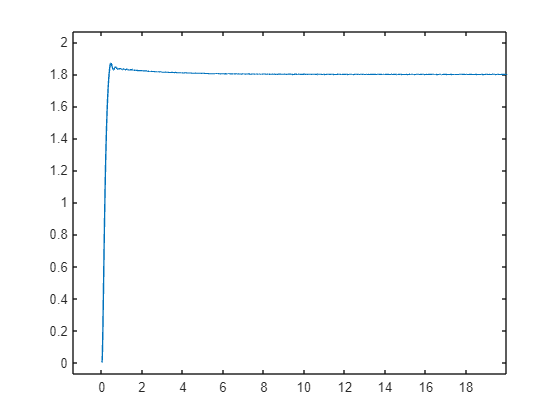

y_exp = squeeze(sim_hardware.Data);
time_vec = sim_hardware.Time;
plot(time_vec, y_exp);

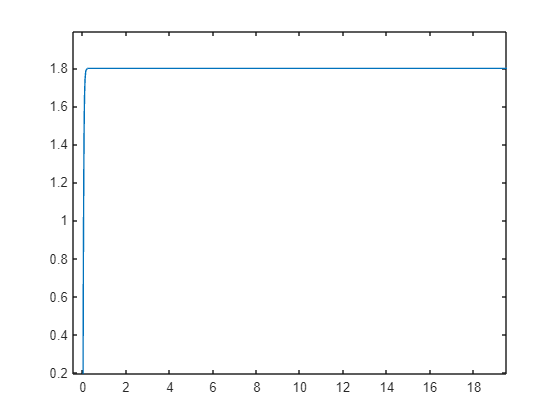

y_sim = squeeze(out.sim_model.Data);
time_vec_sim = out.sim_model.Time;
plot(time_vec_sim, y_sim);

figure('Name', 'Model vs Experiment Comparison');
plot(time_vec, y_exp, 'b', 'LineWidth', 1.5); hold on;
plot(time_vec_sim, y_sim, 'r--', 'LineWidth', 1.5);
legend('Hardware Experiment', 'Simscape Model', 'Location', 'SouthEast');
title('Step Response Comparison: Simscape vs. Hardware');
xlabel('Time (s)');
ylabel('Output (Counts or Rad/s)');
grid on;

% Calculate Metrics using 'stepinfo'
% Note: We crop the data to start AFTER the step for accurate calculation
info_exp = stepinfo(y_exp(time_vec > 0), time_vec(time_vec > 0), 1.8);
info_sim = stepinfo(y_sim(time_vec_sim > 0), time_vec_sim(time_vec_sim > 0), 1.8);

% Display Results
fprintf('--- Performance Metrics ---\n');

--- Performance Metrics ---


fprintf('Metric          | Hardware      | Simscape\n');

Metric          | Hardware      | Simscape


fprintf('----------------|---------------|--------------\n');

----------------|---------------|--------------


fprintf('Rise Time (s)   | %.4f        | %.4f\n', info_exp.RiseTime, info_sim.RiseTime);

Rise Time (s)   | 0.2266        | 0.0569


fprintf('Settling Time(s)| %.4f        | %.4f\n', info_exp.SettlingTime, info_sim.SettlingTime);

Settling Time(s)| 0.9406        | 0.1095


fprintf('Overshoot (%%)   | %.2f%%        | %.2f%%\n', info_exp.Overshoot, info_sim.Overshoot);

Overshoot (%)   | 3.91%        | 0.00%
